# Clustering

The function Clustering allows to cluster a matisse object containing cell/bin information based on expression patterns. 

**Input: **Matisse object (it can be both cells or bins) 

         -Number of clusters

         -Method: three main methods area available in this version ('Hierarchical' ,'umap'[dbscan clustering] or 'kmeans') 

**Output:** Matisse object with clustered data

**Example**

Here you have the example of how to use the function. First we load the bins, summarized in a matisse object

load ('data\Matisse objects\bins_mousebins.mat');

Then we run the function. First we run it and we try to find 10 clusters with the method 'hierarchical'. Note that we need to select the genes that go in the analysis as a first step. 

The DBSCAN algorithm applied when using 'umap' performs de novo clustering, so the number of clusters specified will not be taken into account with this method. 

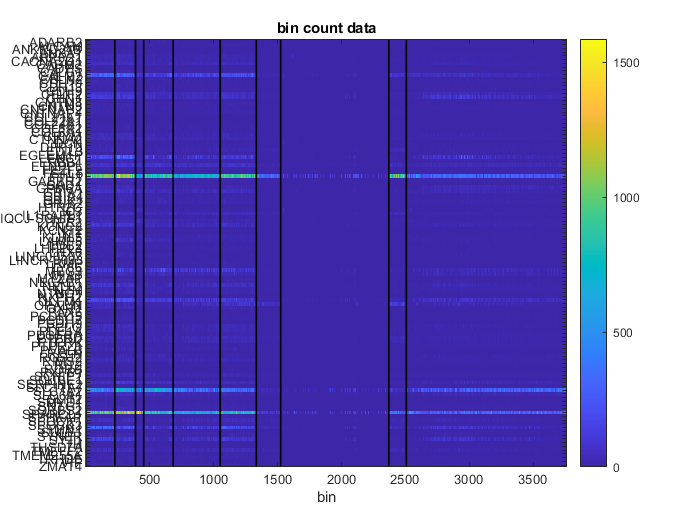

BINS_HIERARCHICAL=Clustering(BINS,10,'hierarchical');

Now we try to find the same number of clusters, but trying the kmeans method

Starting kmeans clustering with 500 replicates..


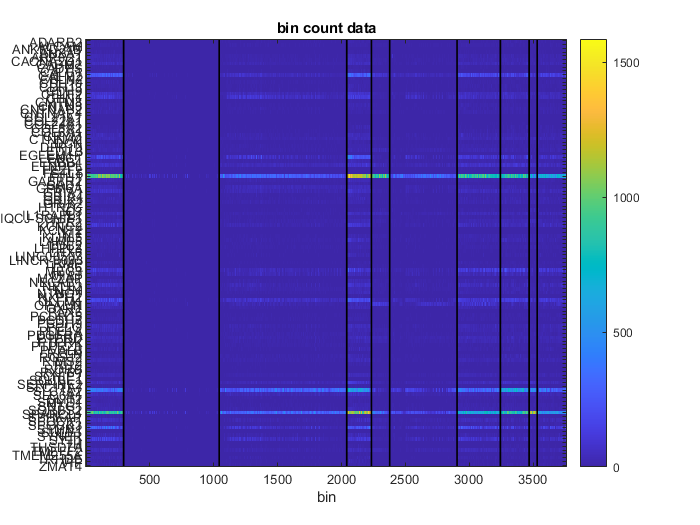

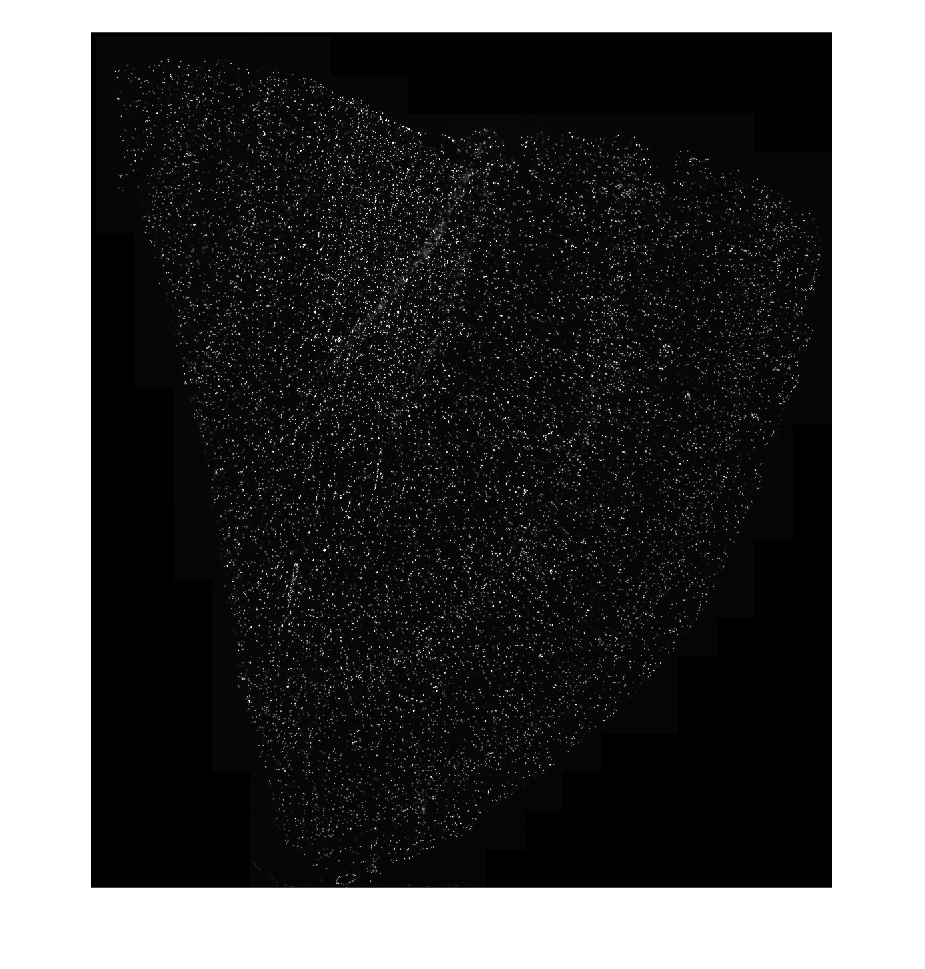

BINS_KMEANS=Clustering(BINS,10,'kmeans');